# EMAT30007 Applied Statistics

# Worksheet 4: Hypothesis testing

## Nikolai Bode

This worksheet focusses on the material covered in Lecture 4: testing hypotheses.

## 1. z-test for a proportion: Exit polls

You are conducting an exit poll for a referendum. You ask 100 voters at random how they voted. You have 45% of yes votes in your sample.

- Is there significant evidence at the $\alpha =1%$ level that the yes vote lost the referendum?

- How many voters are needed before 45% of yes becomes significantly smaller than 50% at the $\alpha =1%$level?

***Solution***

- $H_0$: the fraction of yes votes in the population, $q$, is not smaller than $q_0 =0\ldotp 5$.

- Test statistic:$\hat{p} =\bar{x} =0\ldotp 45$

- Sampling distribution: Normal $\bar{X} ~N\left(p_0 ,p_0 \left(1-p_0 \right)/n\right)$

% true value
q0 = 0.5;
mu = q0;
n = 100;
sigma = (q0*(1-q0)/n)^0.5;
observation = 0.45;
% left-tailed p-value
pval = normcdf(observation, mu, sigma)

pval = 0.1587

% significance level
alpha = 0.01;
% check
[h, p, ci, zval] = ztest(observation, mu, sigma, 'alpha', alpha, 'tail', 'left')

h = 0

p = 0.1587

ci =       -Inf
    0.5663


zval = -1.0000

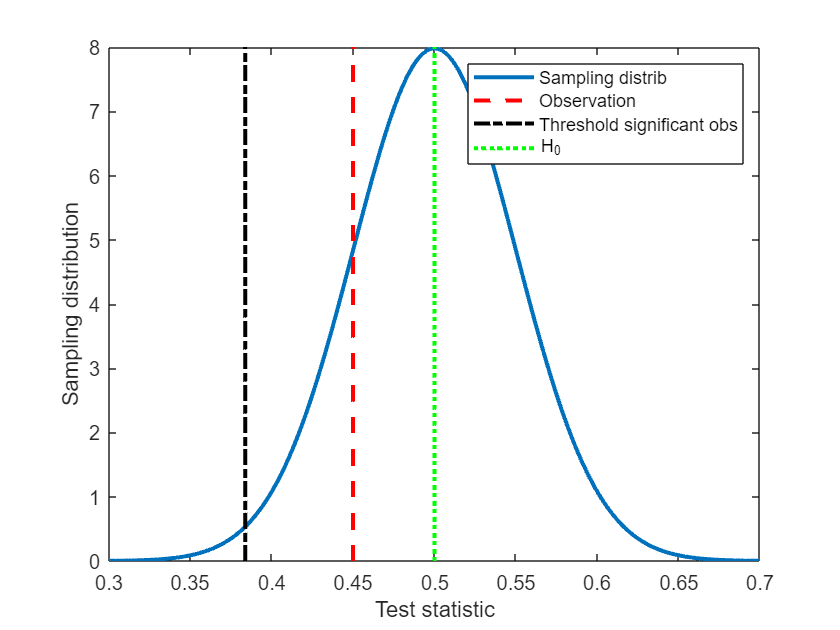

% plot
clf;
xx = 0.3:0.001:0.7;
plot(xx, normpdf(xx, mu, sigma), '-', 'LineWidth', 2);
hold on
yL = get(gca,'YLim');

line([observation, observation],yL,'Color','r','LineWidth',2,'LineStyle','--')
line([norminv(alpha, mu, sigma), norminv(alpha, mu, sigma)],yL,'Color','k','LineWidth',2,'LineStyle','-.')
line([mu, mu],yL,'Color','g','LineWidth',2,'LineStyle',':')
legend('Sampling distrib', 'Observation', 'Threshold significant obs', 'H_0')
set(gca, 'FontSize', 10.0);
xlabel('Test statistic')
ylabel('Sampling distribution')

Given that $p>\alpha$, the fraction of yes is not significanty smaller than 0.5 and we cannot reject the null hypothesis.

% n needed for 0.45 to be 1% significant
n = ceil(((q0*(1-q0))^0.5/(observation - mu) * norminv(alpha))^2)

n = 542

sigma = (q0*(1-q0)/n)^0.5;
observation = 0.45;
% left-tailed p-value
pval = normcdf(observation, mu, sigma)

pval = 0.0100

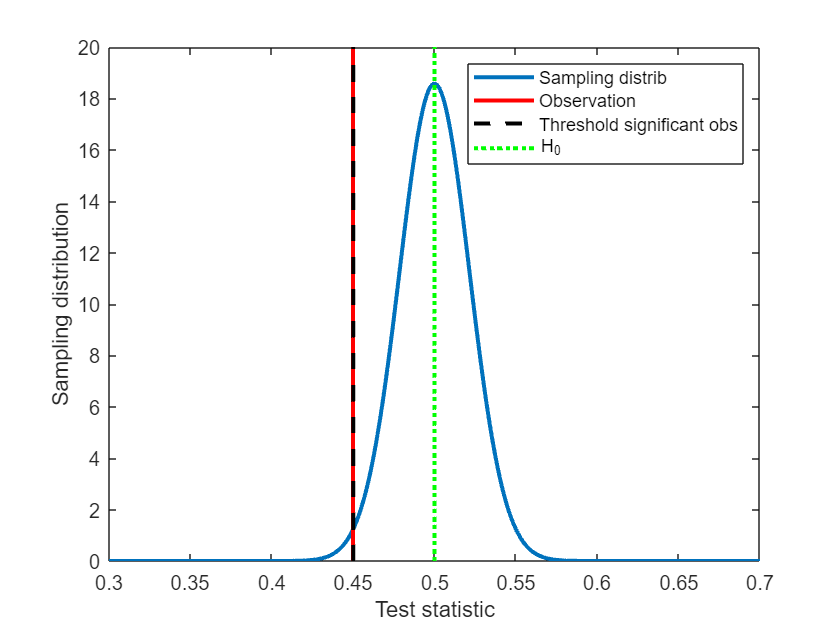

% significance level
alpha = 0.01;
% plot
clf;
xx = 0.3:0.001:0.7;
plot(xx, normpdf(xx, mu, sigma), '-', 'LineWidth', 2);
hold on
yL = get(gca,'YLim');
line([observation, observation],yL,'Color','r','LineWidth',2,'LineStyle','-')
line([norminv(alpha, mu, sigma), norminv(alpha, mu, sigma)],yL,'Color','k','LineWidth',2,'LineStyle','--')
line([mu, mu],yL,'Color','g','LineWidth',2,'LineStyle',':')
legend('Sampling distrib', 'Observation', 'Threshold significant obs', 'H_0')
set(gca, 'FontSize', 10.0);
xlabel('Test statistic')
ylabel('Sampling distribution')

## 2. Paired t-test

A streaming media service aims to increase the time its users spend on the website. To this end, a new version of the website has been released, which is expected to be more engaging than the old version. To test this hypothesis, $n=200$ users have been randomly selected and their website usage has been monitored for two weeks, one week before the website update and one after. For each user, the minutes spent on the old and new versions of the website ($m_{\textrm{before}}$ and $m_{\textrm{after}}$) have been recorded and saved in the files `m_before.csv` and `m_after.csv`.

- Determine if there has been a significant change in the time spent on the two versions of the website, using a significance level of 0.1%.

To answer the question, assume that the distribution of individual differences $\Delta m=m_{\textrm{after}} -m_{\textrm{before}}$ is Normal with unknown variance and test the hypothesis $\Delta m=0$ with a t-test.

Download the files `m_before.csv` and `m_after.csv` from Blackboard, and place them in Matlab's current folder, which is displayed in the left column, in order to load them using `readmatrix `or `readtable`. The rows in both files correspond to the same user: for example, the value in the first row of `m_before.csv` is the minutes that user #1 spent on the old version of the website and the value in the first row of `m_after.csv` is the minutes the same user #1 spend on the new version of the website.

- $H_0$: the mean $\mu$ of delta_mean is 0.

- Test statistic is the mean of the observed delta mean

% Solution
m_before = readtable("m_before.csv");
m_before = m_before{:,1};
m_after = readtable("m_after.csv");
m_after = m_after{:,1};

% Extract differences
Dm = m_after - m_before;
observation = mean(Dm)

observation = 17.9639

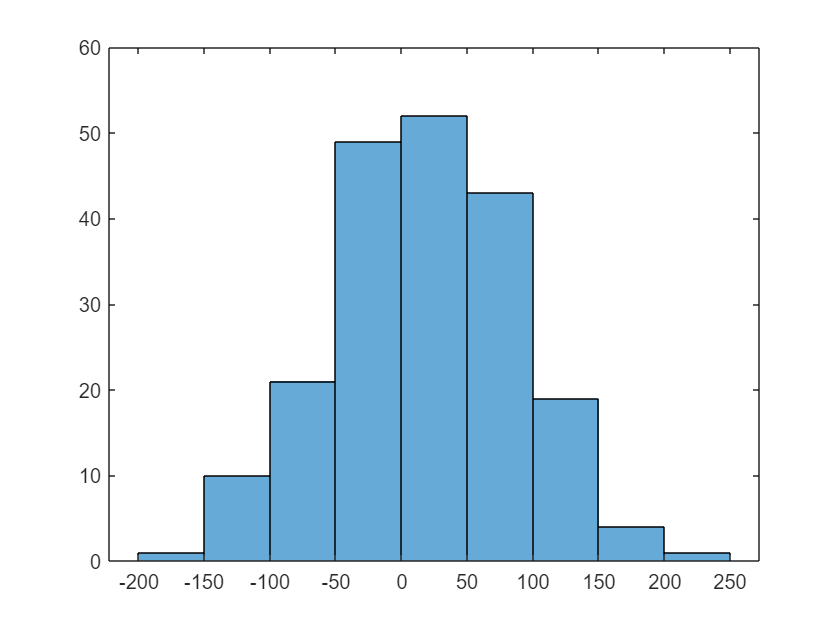

clf
histogram(Dm)

% Sample properties
n = length(Dm);
mu = 0;
sigma = std(Dm) / n^0.5;

% Find tstat = (Xbar - mu) / (S / sqrt(n)
tstat = (observation - mu) / sigma

tstat = 3.6196

% Degrees of freedom
r = n - 1

r = 199

% Calculate two-tailed pval
pval = 2 * (1 - tcdf(tstat, r))

pval = 3.7429e-04

% Significance
alpha = 0.001;

% Perform ttest
[h, p, ci, stats] = ttest(Dm, mu, 'alpha', alpha, 'tail', 'both')

h = 1

p = 3.7429e-04

ci =     1.3871
   34.5407


stats = struct with fields:
    tstat: 3.6196
       df: 199
       sd: 70.1872


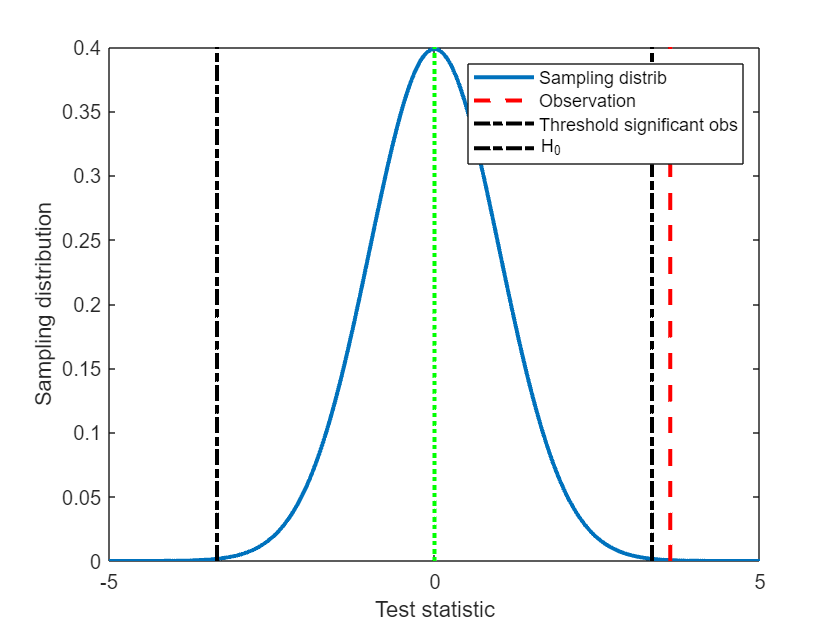

clf;
xx = -5:0.01:5;
plot(xx, tpdf(xx, r), '-', 'LineWidth', 2);
hold on
yL = get(gca,'YLim');
line([tstat, tstat],yL,'Color','r','LineWidth',2,'LineStyle','--')
line([tinv(1 - alpha/2, r), tinv(1 - alpha/2, r)],yL,'Color','k','LineWidth',2,'LineStyle','-.')
line([tinv(alpha/2, r), tinv(alpha/2, r)],yL,'Color','k','LineWidth',2,'LineStyle','-.')
line([0, 0],yL,'Color','g','LineWidth',2,'LineStyle',':')
legend('Sampling distrib', 'Observation', 'Threshold significant obs', 'H_0')
set(gca, 'FontSize', 10.0);
xlabel('Test statistic')
ylabel('Sampling distribution')

The probability to obtain a value of the mean difference more extreme than the observed one (two-tailed p-value) is 0.000374, which is smaller than our significance level 0.001. Hence we reject the null hypothesis which suggests that users spent more time on the new version of the website.

## 3. A/B test

The same streaming media service does another test to verify if the new version of the website is more engaging than the old one. In this second test, two groups of *different* users are randomly selected:

- for each user in the **first group**, the number of minutes spent on the **old version** of the website have been recorded and saved in the file `m_old.csv.`

- for each user in the **second group**, the number of minutes spent on the **new version** of the website have been recorded and saved in the file `m_new.csv`.

Determine if there has been a significant change in the time spent on the two versions of the website, using a significance level of 0.1%.

Download the files `m_old.csv` and `m_new.csv` from Blackboard, and place them in Matlab's current folder, which is displayed in the left column, in order to load them using `readmatrix `or `readtable`.

% Solution
m_old = readtable("m_old.csv");
m_old = m_old{:,1};
m_new = readtable("m_new.csv");
m_new = m_new{:,1};

% Observation is the change of means
mu_new = mean(m_new);
mu_old = mean(m_old);
observation = mu_new - mu_old

observation = 17.9639

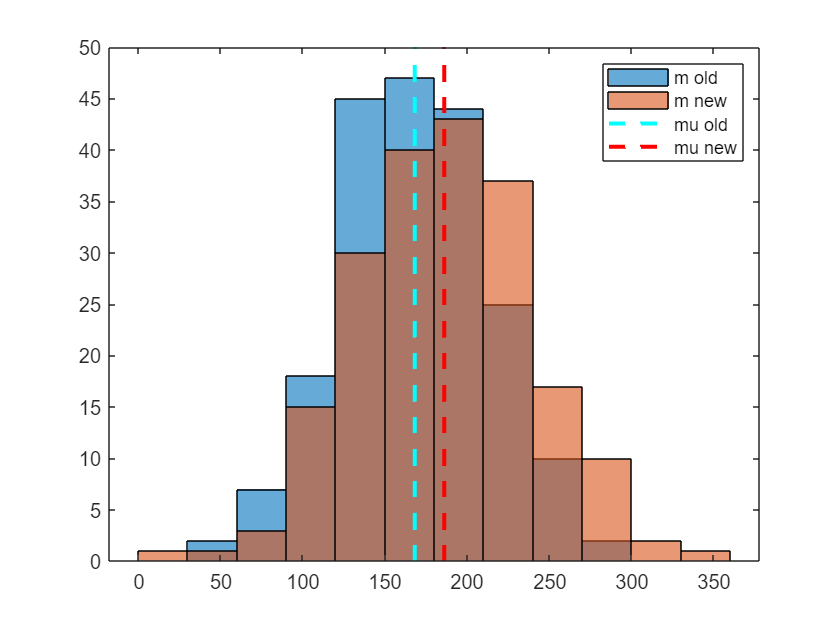

clf
histogram(m_old)
hold on
histogram(m_new)
yL = get(gca,'YLim');
line([mu_old, mu_old],yL,'Color','c','LineWidth',2,'LineStyle','--')
line([mu_new, mu_new],yL,'Color','r','LineWidth',2,'LineStyle','--')
legend('m old', 'm new', 'mu old', 'mu new')

% Welch's t-test
mx = mean(m_new);
sx = std(m_new);
nx = length(m_new);
my = mean(m_old);
sy = std(m_old);
ny = length(m_old);

% Degrees of freedom
r = nx + ny - 2;

% Test stat
tstat = (mx-my) / sqrt(((nx-1)*sx^2 + (ny-1)*sy^2) / r * (1/nx + 1/ny))

tstat = 3.6314

% Pval for two tailed test
pval = 2 * (1 - tcdf(tstat, r))

pval = 3.1869e-04

% Significance of 0.1%
alpha = 0.001

alpha = 1.0000e-03

% Perform ttest
[h, p, ci, stats] = ttest2(m_old, m_new, 'alpha', alpha, 'tail', 'both')

h = 1

p = 3.1869e-04

ci =   -34.3631
   -1.5646


stats = struct with fields:
    tstat: -3.6314
       df: 398
       sd: 49.4678


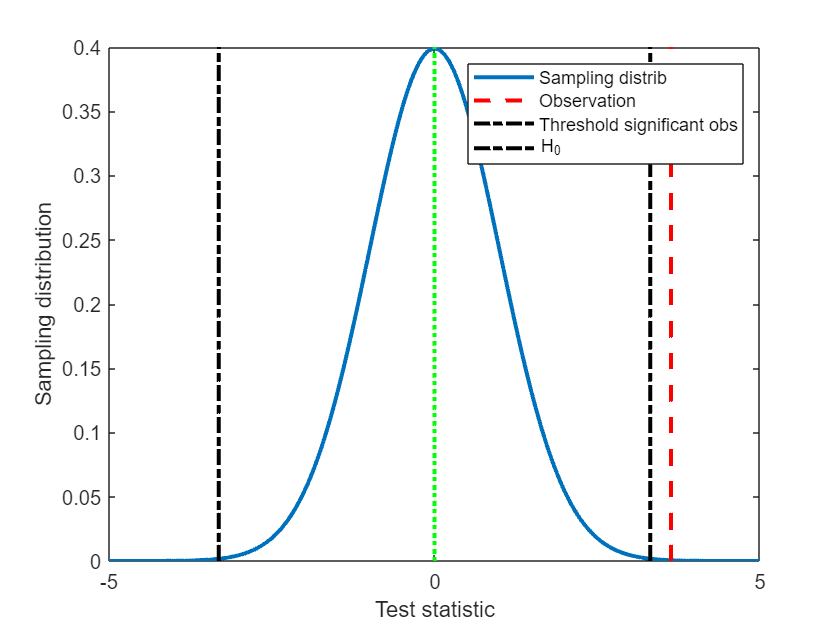

clf;
xx = -5:0.01:5;
plot(xx, tpdf(xx, r), '-', 'LineWidth', 2);
hold on
yL = get(gca,'YLim');
line([tstat, tstat],yL,'Color','r','LineWidth',2,'LineStyle','--')
line([tinv(1 - alpha/2, r), tinv(1 - alpha/2, r)],yL,'Color','k','LineWidth',2,'LineStyle','-.')
line([tinv(alpha/2, r), tinv(alpha/2, r)],yL,'Color','k','LineWidth',2,'LineStyle','-.')
line([0, 0],yL,'Color','g','LineWidth',2,'LineStyle',':')
legend('Sampling distrib', 'Observation', 'Threshold significant obs', 'H_0')
set(gca, 'FontSize', 10.0);
xlabel('Test statistic')
ylabel('Sampling distribution')

## 4. Pregnancy test

In pregnancy tests, the presence of the hCG hormone produced by the placenta after implantation is measured: the test result will be "pregnant" if the hCG concentration is significantly higher than the normal level for non-pregnant individuals.

Assuming that

- in non-pregnant individuals the hCG concentration is Normally distributed with mean 10 and standard deviation 2

- in pregnant individuals the hCG concentration is Normally distributed with mean 18 and standard deviation 3

and considering the null hypothesis "Not pregnant", calculate:

- the value of hCG concentration such that the probability to measure a higher value in a non-pregnant individuals is $\alpha =0\ldotp 1$.

- the probability to commit a type II error (failure to detect pregnancy) if the significance level is $\alpha =0\ldotp 1$.

- the probability to commit a type I error (erroneous detection of pregnancy) if we declare a pregnancy with a hCG concentration of 13 or higher.

***Solution***

% Parameters
mu0 = 10;
sigma0 = 2;

mu1 = 18;
sigma1 = 3;

alpha = 0.1;

% value of hCG concentration such that the probability to measure
% a higher value in a non-pregnant individual is 0.1.
observation = norminv(1-alpha,mu0,sigma0)

observation = 12.5631

%the probability to commit a type II error (failure to detect pregnancy) 
% if the significance level is 0.1
beta = normcdf(observation, mu1, sigma1)

beta = 0.0350

% the probability to commit a type I error (erroneous detection of pregnancy) 
% if we declare a pregnancy with a hCG concentration of 13 or higher.
observation = 13;

alpha = 1 - normcdf(observation, mu0, sigma0)

alpha = 0.0668

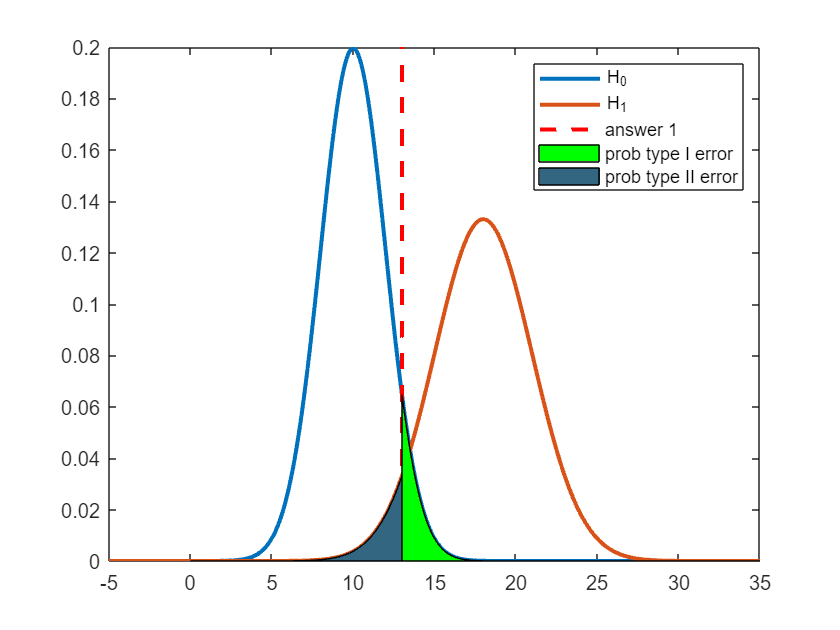

% plot
clf
x = -5:0.1:35;
plot(x, normpdf(x, mu0, sigma0), '-', 'LineWidth', 2);
hold on
plot(x, normpdf(x, mu1, sigma1), '-', 'LineWidth', 2);
hold on
yL = get(gca,'YLim');
line([observation,observation],yL,'Color','r','LineWidth',2,'LineStyle','--')
%xline(observation, '--r', 'LineWidth', 2);
hold on
r = observation:0.1:35;
inBetween = [normpdf(r, mu0, sigma0), fliplr(zeros(1, length(r)))];
fill([r fliplr(r)], inBetween, 'g');
hold on
r = 0:0.1:observation;
inBetween = [normpdf(r, mu1, sigma1), fliplr(zeros(1, length(r)))];
fill([r fliplr(r)], inBetween, [0.2 0.4 0.5]);
legend('H_0', 'H_1', 'answer 1', 'prob type I error', 'prob type II error')

## 5. Pregnancy test 2 (confusion matrix)

A pharmaceutical company conducted an experiment on a new commercial pregnancy test they have developed.

- A total of 100 random participants took part in the experiment

- 20% of the participants were actually pregnant.

- The probability of a false positive (erroneous detection of pregnancy) is 0.3

- The probability of a false negative (failure to detect pregancy) is 0.1

Compute all the entries of the confusion matrix and calculate:

- the accuracy of the test, i.e. the fraction of correct predictions

- the probability to be pregnant if the test result is negative ("not pregnant")

- the probability of not being pregnant if the test is positive ("pregnant")


$$\mathrm{TN}+\mathrm{FP}+\mathrm{TP}+\mathrm{FN}=100$$



$$\frac{\mathrm{TN}+\mathrm{FP}}{\mathrm{TN}+\mathrm{FP}+\mathrm{TP}+\mathrm{FN}}=0\ldotp 2$$



$$\frac{\mathrm{FP}}{\mathrm{TP}+\mathrm{FP}}=0\ldotp 3$$



$$\frac{\mathrm{FN}}{\mathrm{FN}+\mathrm{TP}}=0\ldotp 1$$



$$\begin{array}{l}
\mathrm{TN}=56\\
\mathrm{FN}=2\\
\mathrm{FP}=24\\
\mathrm{TP}=18
\end{array}$$



$$\frac{\mathrm{TN}+\mathrm{TP}}{\mathrm{TN}+\mathrm{FP}+\mathrm{TP}+\mathrm{FN}}=0\ldotp 74$$



$$\frac{\mathrm{TN}}{\mathrm{TN}+\mathrm{FP}}=0\ldotp 03$$



$$\frac{\mathrm{FP}}{\mathrm{FP}+\mathrm{TP}}=0\ldotp 57$$
